%{
if we are trying to find the roots of f(x), we can transition to finding
the fixed points of the g(x) = x which is equivalent to f(x). We start with
an initial guess that we set. it is best to graph the equation first to get
a good idea of an initial guess. we then use g(x) with our initial guess
for our first iteration. if the error( abs(curr_guess - prev_guess)) is
less than our error tolerance we have found a good enough root. we then use
g(x) on the value it gave out before. 
%}


%args for problem
g = @(x) exp(-x);
tol = 10^-10;
N = 1000;
x0 = .35;

%we use a function g(x) to find the fixed point of a function which will be the zeros
function [c,n,err] = fixed_point_method(g,x0,tol,N)
    %set counter to 0
    n = 0;
    %make a variable x to be the initial guess
    x = x0;
    %while the counter is less than the max number of iterations
    while n < N
        %predict c
        c = g(x);
        %we find error by absolute value of current guess - x 
        err = abs(c - x);
        if err < tol
            break;
        end
        n = n + 1;
        x = c;
    end

end

[c,n,err] = fixed_point_method(g,x0,tol,N)

c = 0.5671

n = 39

err = 9.0008e-11

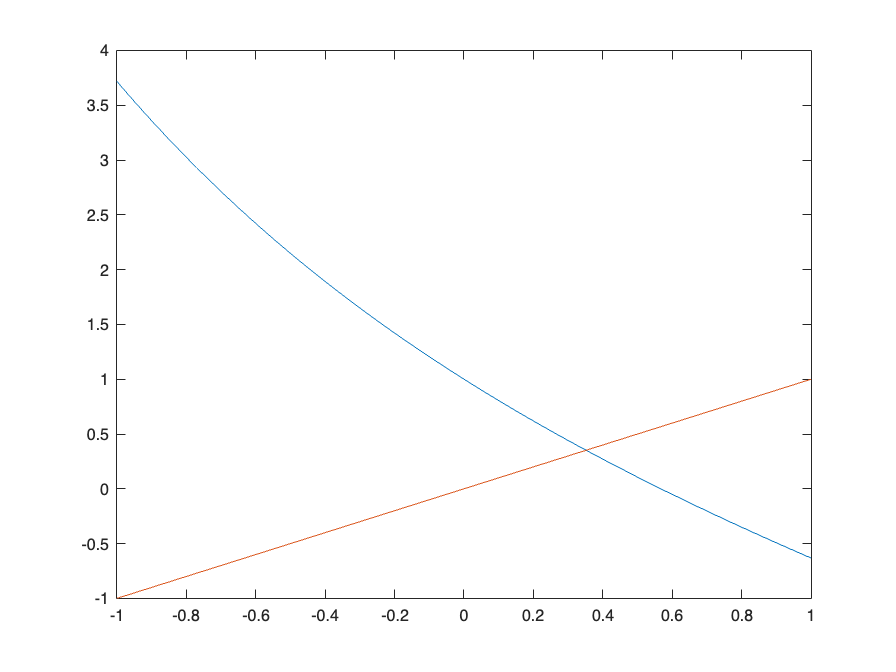

%f = @(x) exp(-x) - x;

%plot
x = -1:.01:1;
y = exp(-x) - x;
plot(x,y)
hold on;
x2 = -1:.01:1;
y2 = x2;
plot(x2,y2)